
%% 171和173分组测量 %%

close all
clear all
colors=npg(10); % Ten basic colors
tpi = 2*pi;

maindir='\\Artemis-pc\Data\2026-07-15\Abs-225\';   % 相位数据
main_dir_0=maindir;
load([maindir,'\population.mat']);
sz = (s1-s2)./(s1+s2);
%sz([12:-1:9]) = [];   % 注意是否删除异常点

maindir='\\Artemis-pc\Data\2026-07-15\Abs-130\';   % 171对比度
load([maindir,'\repeat_amp.mat']);
a171 = amp(1)-0*a_sigma(1);
as171 = a_sigma(1);
a171_plus = a171+1*as171;
a171_minus = a171-1*as171;

maindir='\\Artemis-pc\Data\2026-07-15\Abs-143\';   % 173对比度
load([maindir,'\repeat_amp.mat']);
a173 = amp(1)-0*a_sigma(1);
as173 = a_sigma(1);
a173_plus = a173+1*as173;
a173_minus = a173-1*as173;

save_data = 1;



% ！！注意 周期数 和 进动时间 ！！ %

Yb_list = [171 173];   % 元素序列，必须交错成对
Yb_len = length(Yb_list);
if mod(Yb_len,2)
    error('Yb list error!');
end

ts = 10;   % s,不包含旋转位移台时间
ms171 = 73.05;   % ms,171
ms173 = 71.9;   % ms,173

N171 = 1267.25;
N173 = 1745.25;

coefficient171 = 2-4*(N171-floor(N171));   % 上坡+1,下坡-1
coefficient173 = 2-4*(N173-floor(N173));   % 上坡+1,下坡-1

ROT_T = 4020;   % ms,前后转台转动总时间
wait1 = 4;   % ms
wait2 = 46;   % ms

precession171 = ts*1e3 + ms171;   % 时序可设置的进动时间
tau171 = precession171 + ROT_T + wait1*2 + wait2;   % 包括转台转动时间，前后各2s
precession173 = ts*1e3 + ms173;   % 时序可设置的进动时间
tau173 = precession173 + ROT_T + wait1*2 + wait2;   % 包括转台转动时间，前后各2s

%N171 = floor((tau171-ms171)/T171);
%N173 = floor((tau173-ms173)/T173);


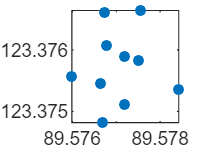


Rlen = floor(length(sz)/Yb_len);   % 频率比组数
delete_num = Rlen*Yb_len+1;   % 该数以后，相位不成组
sz([delete_num:end]) = [];
sz_all = reshape(sz,Yb_len,Rlen);

for k = 1:Yb_len
    if Yb_list(k) == 171
        sz171 = sz_all(k,:);
        dp171 = real(asin(sz171/a171));
        p171 = coefficient171*dp171 + tpi*N171;
        f171 = p171/(tau171*1e-3)/tpi;   % frequency Hz

        % a171+a_sigma171 %
        dp171_plus = real(asin(sz171/a171_plus));
        p171_plus = coefficient171*dp171_plus + tpi*N171;
        f171_plus = p171_plus/(tau171*1e-3)/tpi;   % frequency Hz

        % a171-a_sigma171 %
        dp171_minus = real(asin(sz171/a171_minus));
        p171_minus = coefficient171*dp171_minus + tpi*N171;
        f171_minus = p171_minus/(tau171*1e-3)/tpi;   % frequency Hz

    elseif Yb_list(k) == 173
        sz173 = sz_all(k,:);
        dp173 = real(asin(sz173/a173));
        p173 = coefficient173*dp173 + tpi*N173;
        f173 = p173/(tau173*1e-3)/tpi;   % frequency Hz

        % a173+a_sigma173 %
        dp173_plus = real(asin(sz173/a173_plus));
        p173_plus = coefficient173*dp173_plus + tpi*N173;
        f173_plus = p173_plus/(tau173*1e-3)/tpi;   % frequency Hz

        % a173-a_sigma173 %
        dp173_minus = real(asin(sz173/a173_minus));
        p173_minus = coefficient173*dp173_minus + tpi*N173;
        f173_minus = p173_minus/(tau173*1e-3)/tpi;   % frequency Hz

    end
    if mod(k,2) == 0
        Rlist((k/2-1)*Rlen+1:k/2*Rlen) = f171./f173;
        Rlist_171plus((k/2-1)*Rlen+1:k/2*Rlen) = f171_plus./f173;
        Rlist_171minus((k/2-1)*Rlen+1:k/2*Rlen) = f171_minus./f173;
        Rlist_173plus((k/2-1)*Rlen+1:k/2*Rlen) = f171./f173_plus;
        Rlist_173minus((k/2-1)*Rlen+1:k/2*Rlen) = f171./f173_minus;
    end
end

figure;
plot(f171,f173,'.','MarkerSize',14);


Rm = mean(Rlist);
dR = std(Rlist)/sqrt(length(Rlist)-1);
Rm_171plus = mean(Rlist_171plus);
Rm_171minus = mean(Rlist_171minus);
Rm_173plus = mean(Rlist_173plus);
Rm_173minus = mean(Rlist_173minus);
dRa171 = (Rm_171plus-Rm_171minus)/2;
dRa173 = (Rm_173plus-Rm_173minus)/2;
Rstd = sqrt(dR^2+dRa171^2+dRa173^2);


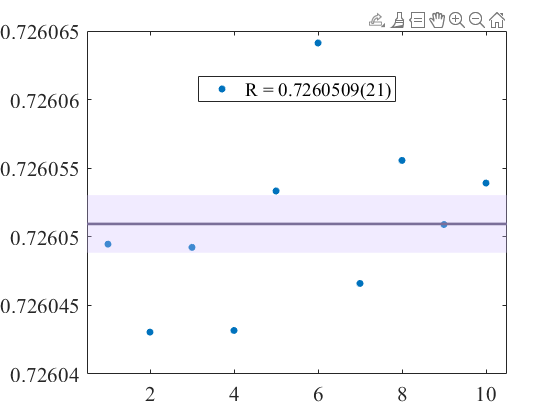


f1 = figure; hold on;
plot(1:Rlen,Rlist,'.','MarkerSize',18);
set(gca,'FontSize',16,'FontName','times new roman');

n1 = [1 2 3 4];
patch_list = [0 Rm-Rstd ; Rlen+1 Rm-Rstd ; Rlen+1 Rm+Rstd ; 0 Rm+Rstd];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');
plot([0 Rlen+1],[Rm Rm],Color=[0.48 0.43 0.60],LineWidth=2);
legend(['R = ',num2str(Rm,'%.7f'),'(',num2str(Rstd*1e7,'%.0f'),')'],...
    'Location','best');

grid off;
box on;
xlim([0.5 Rlen+0.5]);

set(f1,'Visible','on');


% if save_data == 1
%     savefig(f1,[main_dir_0,'Rture.fig']);
%     saveas(f1,[main_dir_0,'Rture.png']);
%     save([main_dir_0,'\seperate_Rture.mat']);
% end


if save_data == 1
    savefig(f1,[main_dir_0,'R.fig']);
    saveas(f1,[main_dir_0,'R.png']);
    save([main_dir_0,'\seperate_R.mat']);
end